%CS170 Project 2 Live Script File

%number of features
data = zeros([2,10])

data =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0



best_feature_accuracies = [];

current_set_of_features = [];
for i = 1:size(data,2)
    disp(['On level ',num2str(i),' of search tree']);
    feature_to_add_at_this_level = [];
    best_so_far_accuracy = 0;
    
    for k = 1:size(data,2)
        if isempty(intersect(current_set_of_features,k))
            disp(['---Considering adding feature ', num2str(k)]);
            accuracy = Leave_One_Out_Cross_Validation(data,current_set_of_features,k);
            
            if accuracy > best_so_far_accuracy
                best_so_far_accuracy = accuracy;
                feature_to_add_at_this_level = k;
            end
        end
    end
    current_set_of_features(i) = feature_to_add_at_this_level
    best_feature_accuracies(i) = best_so_far_accuracy;
    disp(['On level', num2str(i),', added feature ',num2str(feature_to_add_at_this_level),'.']);
end

On level 1 of search tree


---Considering adding feature 1
---Considering adding feature 2
---Considering adding feature 3
---Considering adding feature 4
---Considering adding feature 5
---Considering adding feature 6
---Considering adding feature 7
---Considering adding feature 8
---Considering adding feature 9
---Considering adding feature 10


current_set_of_features = 10

On level1, added feature 10.


On level 2 of search tree


---Considering adding feature 1
---Considering adding feature 2
---Considering adding feature 3
---Considering adding feature 4
---Considering adding feature 5
---Considering adding feature 6
---Considering adding feature 7
---Considering adding feature 8
---Considering adding feature 9


current_set_of_features =     10     3


On level2, added feature 3.


On level 3 of search tree


---Considering adding feature 1
---Considering adding feature 2
---Considering adding feature 4
---Considering adding feature 5
---Considering adding feature 6
---Considering adding feature 7
---Considering adding feature 8
---Considering adding feature 9


current_set_of_features =     10     3     4


On level3, added feature 4.


On level 4 of search tree


---Considering adding feature 1
---Considering adding feature 2
---Considering adding feature 5
---Considering adding feature 6
---Considering adding feature 7
---Considering adding feature 8
---Considering adding feature 9


current_set_of_features =     10     3     4     9


On level4, added feature 9.


On level 5 of search tree


---Considering adding feature 1
---Considering adding feature 2
---Considering adding feature 5
---Considering adding feature 6
---Considering adding feature 7
---Considering adding feature 8


current_set_of_features =     10     3     4     9     5


On level5, added feature 5.


On level 6 of search tree


---Considering adding feature 1
---Considering adding feature 2
---Considering adding feature 6
---Considering adding feature 7
---Considering adding feature 8


current_set_of_features =     10     3     4     9     5     7


On level6, added feature 7.


On level 7 of search tree


---Considering adding feature 1
---Considering adding feature 2
---Considering adding feature 6
---Considering adding feature 8


current_set_of_features =     10     3     4     9     5     7     6


On level7, added feature 6.


On level 8 of search tree


---Considering adding feature 1
---Considering adding feature 2
---Considering adding feature 8


current_set_of_features =     10     3     4     9     5     7     6     2


On level8, added feature 2.


On level 9 of search tree


---Considering adding feature 1
---Considering adding feature 8


current_set_of_features =     10     3     4     9     5     7     6     2     8


On level9, added feature 8.


On level 10 of search tree


---Considering adding feature 1


current_set_of_features =     10     3     4     9     5     7     6     2     8     1


On level10, added feature 1.


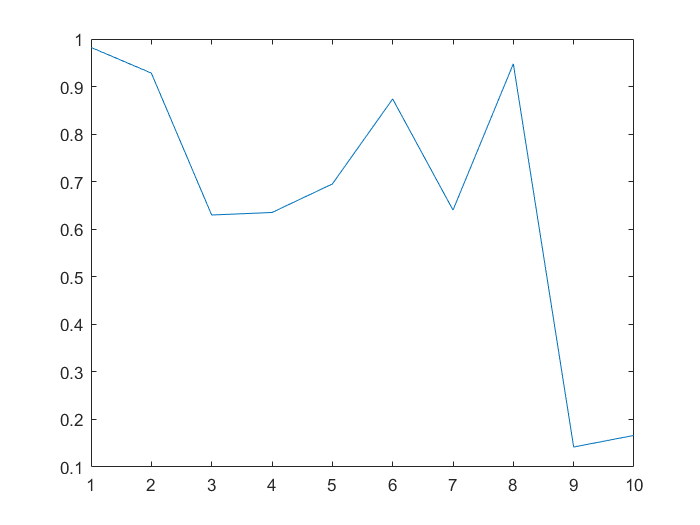



%plot(best_feature_accuracies);

function accuracy = Leave_One_Out_Cross_Validation(data,current_set_of_features,k)
    accuracy = rand;
end